### Temp exponential

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

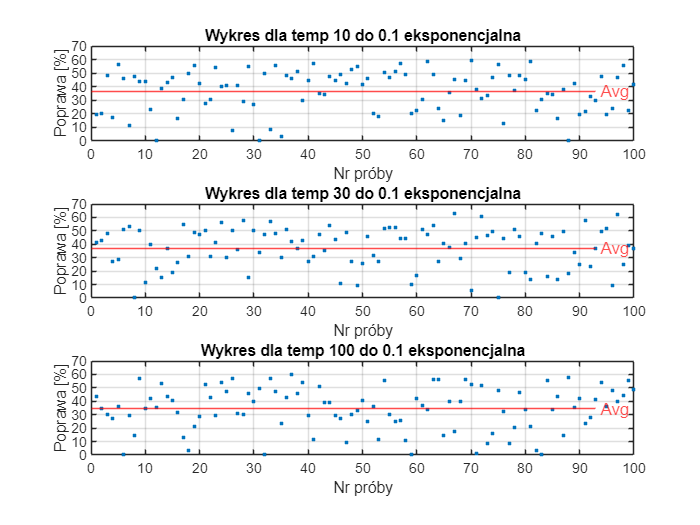

clear all; %#ok<CLALL>
load("results.mat")

max_iter_100_rel_imp = temp10To01Data(temp10To01Data.ExperimentName == "test_temp_10_to_0.1_exponential", {'RelativeImprovement'});
max_iter_1000_rel_imp = temp30To01Data(temp30To01Data.ExperimentName == "test_temp_30_to_0.1_exponential", {'RelativeImprovement'});
max_iter_2000_rel_imp = temp100To01Data(temp100To01Data.ExperimentName == "test_temp_100_to_0.1_exponential", {'RelativeImprovement'});

max_iter_100_rel_imp.RelativeImprovement = max_iter_100_rel_imp.RelativeImprovement * 100;
max_iter_1000_rel_imp.RelativeImprovement = max_iter_1000_rel_imp.RelativeImprovement * 100;
max_iter_2000_rel_imp.RelativeImprovement = max_iter_2000_rel_imp.RelativeImprovement * 100;


max_iter_100_rel_imp_avg = mean(max_iter_100_rel_imp.RelativeImprovement);
max_iter_1000_rel_imp_avg = mean(max_iter_1000_rel_imp.RelativeImprovement);
max_iter_2000_rel_imp_avg = mean(max_iter_2000_rel_imp.RelativeImprovement);

max_iter_100_rel_imp_std = std(max_iter_100_rel_imp.RelativeImprovement);
max_iter_1000_rel_imp_std = std(max_iter_1000_rel_imp.RelativeImprovement);
max_iter_2000_rel_imp_std = std(max_iter_2000_rel_imp.RelativeImprovement);

max_iter_names = ["10 to 0.1"; "30 to 0.1"; "100 to 0.1";];
max_iter_avgs = [max_iter_100_rel_imp_avg; max_iter_1000_rel_imp_avg; max_iter_2000_rel_imp_avg];
max_iter_stds = [max_iter_100_rel_imp_std; max_iter_1000_rel_imp_std; max_iter_2000_rel_imp_std];

exponential_temp_comparison = table(max_iter_names, max_iter_avgs, max_iter_stds, 'VariableNames', {'temp', 'avg', 'std'});

max_value = max([max(max_iter_100_rel_imp.RelativeImprovement), ...
    max(max_iter_1000_rel_imp.RelativeImprovement), ...
    max(max_iter_2000_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_100 = max(histcounts(max_iter_100_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_1000 = max(histcounts(max_iter_1000_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_2000 = max(histcounts(max_iter_2000_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_100, max_count_1000, max_count_2000]) + 10;

figure;

subplot(3, 1, 1);
plot(max_iter_100_rel_imp.RelativeImprovement, '.');
yline(max_iter_100_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla temp 10 do 0.1 eksponencjalna');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 2);
plot(max_iter_1000_rel_imp.RelativeImprovement, '.');
yline(max_iter_1000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla temp 30 do 0.1 eksponencjalna');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(3, 1, 3);
plot(max_iter_2000_rel_imp.RelativeImprovement, '.');
yline(max_iter_2000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla temp 100 do 0.1 eksponencjalna');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

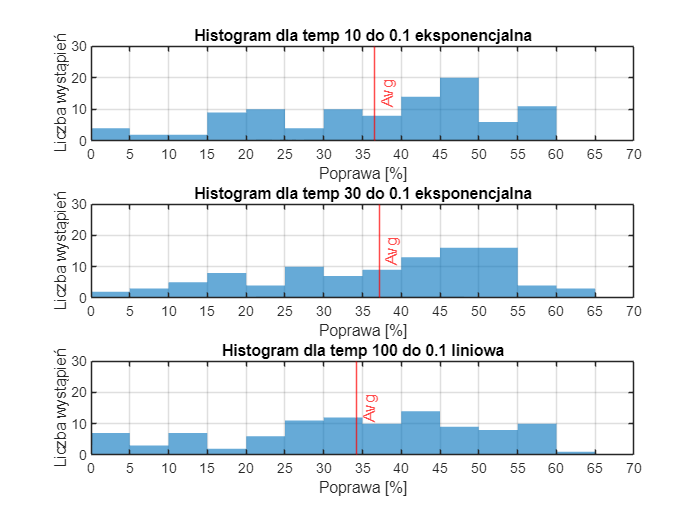


figure;

% Histogram dla max_iter_100_rel_imp
subplot(3, 1, 1);
histogram(max_iter_100_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_100_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla temp 10 do 0.1 eksponencjalna');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla max_iter_1000_rel_imp
subplot(3, 1, 2);
histogram(max_iter_1000_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_1000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla temp 30 do 0.1 eksponencjalna');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla max_iter_2000_rel_imp
subplot(3, 1, 3);
histogram(max_iter_2000_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(max_iter_2000_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla temp 100 do 0.1 liniowa');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);


exponential_temp_comparison

exponential_temp_comparison = 3×3 table
        temp         avg       std  
    ____________    ______    ______

    "10 to 0.1"     36.528    15.189
    "30 to 0.1"     37.136    15.141
    "100 to 0.1"    34.272     16.12
